# **Visualisation of Isosurfaces within a reconstructed APT tip**

**Voxelisation of atom probe data in 3D, calculating concentrations, creating isosurfaces**

In order to visualise isosurfaces with an APT data set, it is necessary to voxelise the data and calculate the corresponding concentrations. Also, it is essential, that the decomposed pos variable (*pos*) is present in the workspace. These steps are extensively described in the live script ***FirstSteps***.

### Create grid vectors

In the first step, a set of grid vectors in 3D binning is created by the function *binVectorsFromDistance*. As inputs the distance variable and the bin width need to be specified. For the 3D binning the x, y, and z coordinates of the pos file are predestined as the *dist* input. The bin width can be either isotropic (e.g., [1 1 1] or anisotropic (e.g., [1 2 2]), whereas the positions in *dist* correspond with the position within *bin*. Here, as mode only *'distance'* is possible since the binning needs to be executed in three dimensions.

dist = [pos.x pos.y pos.z]; % distance variable for the binning
bin = [1 1 1]; % bin width of each voxel in the direction of the defined distances, in nm
mode = 'distance';
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates the bin centers and bin edges of a grid
  

### Voxelisation

In the next section the voxelisations of both the point cloud stored in *pos* and for the specific ion species, of which the isosurface should be created, is performed. Also, the concentration of the input species is calculated

gridVec = binCenters; % renaming of bin centers, which will act as grid vectors
vox = posToVoxel(pos,gridVec); % voxelisation of all species
species = {'Si'}; % input of the wanted species, e.g. {'H' 'C'}
voxIon = posToVoxel(pos,gridVec,species); % voxelisation of only the input species
conc = voxIon./vox; % calculation of the concentration of the wanted species
  

### Create the isosurface

In the final step the isosurface is calculated and subsequently visualised. The *isovalue* can be any number between 0 and 100 (in at.%). For the visualisation, a *RGB* color code for the faces must be defined.

NOTE: When using the function *isosurface*, the input *isovalue* must be either a string or a character array. 

isovalue = "25"; % specification of the isovalue in at.%
fv = isosurface(gridVec{2},gridVec{1},gridVec{3},conc,isovalue); % creation of the isosurface with faces and vertices
RGB = [1 1 0]; % RGB color code for the isosurface faces
p = patch(fv, 'FaceColor', RGB); axis equal; rotate3d on; % visualisation of the created isosurface
axisSpatialAptify; % change into APT common view
  

### *isosurfaceWidget* app

The user can also use the *isosurfaceWidget* app to adjust the isovalue and find the best value that suits the user's dataset. In addition, the user can change the color of the patches and split the entire patch in several patches. These patches can be exported into the Matlab workspace for further data analysis.

species = {'Si'}; % numerator of concentration (conc = species./speciesAll); 
% the ion(s), of which the user wants to build a patch on the basis of an isovalue 
speciesAll = {'Hf','Si', 'B'} ; % denominator of concentration (conc = species./speciesAll); 
% list of all other species, but elements of input species must also be included
bin = 1; % bin width of each voxel in the direction of the defined distances, in nm 
load colorScheme.mat; % loads a color scheme into Matlab workspace
% ax =  ; % if already axes exist, where the patch(es) should be plotted
  

The *species* is the ion for the patch. If *speciesAll* is not empty, the concentration of the species is calculated in correlation to the ions in *speciesAll*. If an empty cell array *{}* is parsed for speciesAll, the user calculates the patch based on the counts of species. 

Matlab live script does not support the manipulation of a figure via an app with the live script. The user hast to copy and pase the following line in the command window:

% isosurfaceWidget(pos,species,speciesAll,bin,colorScheme,ax);

The app will open and the user can start to change the isovalue with the slider below the histogram. The patches in the figure will adapt to the new isovalue. By clicking the *change color* button, the user can change the color of the patch. Patches consisting of fewer vertices than a specific value (defined in the edit field under the *filter patch size* button), can be excluded by klicking the *filter patch size* button. With the *split surfaces* button, the entire patch will be split to different coherent patches that can be exported into the workspace with the *create variable* button. 

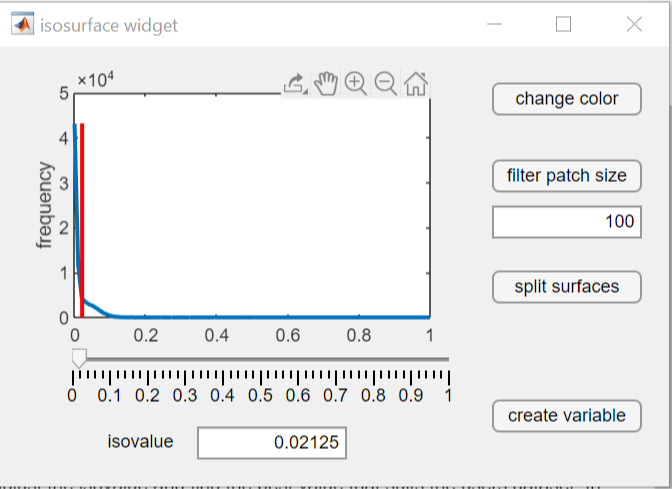

### Plot the isosurface into an ion plot

Sometimes it is helpful to plot the isosurface with the residual ions in one plot.

Therefore, firstly a plot with the ions must be plotted. Subsequently, the isosurface can be plotted into the same coordinate system. 

*fv * is the variable created by the *isosurface* function or with the *isosurface widget app*. The user can also use an isosurface created with external software (e.g. Blender) and load the isosurface into Matlab (see section below). 

species = {'C'}; % the ions that the user wants to plot
sample = 1; % subset of atoms either as a fraction (value <1) or number of atoms (value >1)
size = 1; % size of the single atoms in the plot
pPlot = scatterPlotPosData(pos,species,sample,colorScheme,size,axes(figure()));
ax = pPlot.Parent;
patch(ax,obj1,'DisplayName','Isosurface'); % create patch inside the axes ax
 

The color can be a 3 scalar vector or different written colors as it is in the example. By opening the property inspector, it is possible to change the color manually. By changing the variable *'DisplayName' * the user can name the isosurface individually. 

### Plot the ions in an isosurface plot

ax = gca; % get the current axes
pPlot = scatterPlotPosData(pos,{'Mo','B'},sample,colorScheme,size,ax); % plot the ions in the axes
 

### Export of an isosurface as an .obj file 

For further data analysis and better visualisation, it is possible to export the isosurface as an .obj file. This file can be imported into 3D computer softwares such as Blender. 

patch = fv;
objName = 'grain boundary'; % name of the isosurface
fileName = 'fileName.obj'; % Name of the created .obj file
patchToObj(patch,objName,fileName)
 

### Import of an isosurface as an .obj file

After data analysis with external software (e.g. Blender) the stored .obj file can imported into Matlab.

The input for the function *objToPatch* is the file name of the desired .obj file (*objFileName*), including the entire file path. If the file is located in the 'Current Folder' no patch needs to be given.

NOTE: It is also possible to select the .obj file manually by using no input (either empty parenthesis or no parenthesis at all). By doing so, a selection box pops up and the user can search for the file.

objFileName = 'isosurface.obj'; % full .obj file name of desired, including the file path
objToPatch(objfilename); 
 